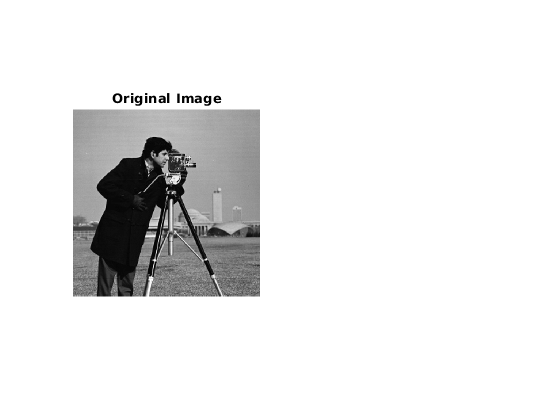

% Implementation of Phase Stretch Transform (PST) in Matlab
% author: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

clc  % clear screen
clear all  % clear all variables
close all   % close all figures

% import original image
filename = 'cameraman.tif';
filepath =strcat('./Test_Images/',filename);
Image_orig=imread(filepath);

% if image is a color image, convert it to grayscale
try
%    Image_orig=rgb2gray(Image_orig);
catch
end

%show the original image
subplot(1,2,1)
imshow(Image_orig)
title('Original Image')


% convert the grayscale image do a 2D double array
Image_orig=double(Image_orig);

% low-pass filtering (also called localization) parameter
handles.LPF=0.21; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=12.14;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;      % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max=0.0019;  % maximum Threshold  (a number between 0 and 1)

% choose to compute the analog or digital edge
Morph_flag = 1 ; %  Morph_flag=0 to compute analog edge and Morph_flag=1 to compute digital edge.

% Apply PST and find features (sharp transitions)
[Edge PST_Kernel]= PST(Image_orig,handles,Morph_flag);

Index exceeds the number of array elements (2).

Error in PST (line 82)
z=linspace(-L,L,Image_orig_size(3));


if Morph_flag ==0
    % show the detected features    
    subplot(1,2,2)
    imshow(Edge/max(max(Edge))*3)
    title('Detected features using PST')
    % save the image
    file_and_extension=strsplit(filename,'.');
    output_path=char(strcat('./Test_Images/',file_and_extension(1),'_edge.tif'));
    imwrite(Edge/max(max(Edge))*3,output_path);
else
    subplot(1,2,2)
    imshow(Edge)
    title('Detected features using PST')
    % save the image
    file_and_extension=strsplit(filename,'.');
    output_path=char(strcat('./Test_Images/',file_and_extension(1),'_edge.tif'));
    imwrite(Edge,output_path);
    % overlay original image with detected features
    overlay = double(imoverlay(Image_orig, Edge/1000000, [1 0 0]));
    figure
    imshow(overlay/max(max(max(overlay))));
    title('Detected features using PST overlaid with original image')
    % save the image
    output_path=char(strcat('./Test_Images/',file_and_extension(1),'_overlay.tif'));
    imwrite(overlay/max(max(max(overlay))),output_path);
end

% show the PST phase kernel gradient
figure
[D_PST_Kernel_x D_PST_Kernel_y]=gradient(PST_Kernel);
mesh(sqrt(D_PST_Kernel_x.^2+D_PST_Kernel_y.^2))
title('PST Kernel phase Gradient')